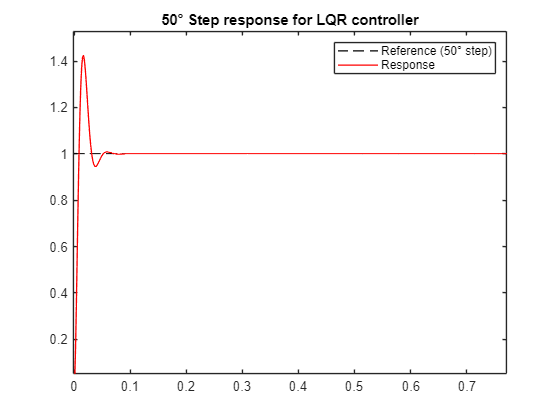

clear all
clc

%% System Definition
% Dynamic model
A = [0, 1; -2, -40];
B = [0; 40];
C = [1, 0];
D = 0;
sys = ss(A,B,C,D);

% Extended Model in CT
%Ae = [0,C; zeros(2,1), A];
%Be = [0;B];
%Ce = [0,C];
%De = D;
%syse = ss(Ae, Be, Ce, De);

% Sampling time
Ts = 0.01e-3;

%% Discretizing the Model
% discretizing the model and then extending
sysD = c2d(sys,Ts,'zoh');
[Phi, Gamma, H, J] = ssdata(sysD);


% poles


% Extending the discrete model
Phie = [1, H; zeros(2,1), Phi];    % Ts*H? -> same as discretizing extended
Gammae = [0;Gamma];
He = [0,H];
Je = J;
sysDe = ss(Phie, Gammae, He, Je, Ts);

% discretizing the extended model
%sysDe = c2d(syse, Ts, 'zoh');
%[Phie, Gammae, He, Je] = ssdata(sysDe);



%% Optimal Feedback Controller
% Cost matrices from Bryson's rule
Q = diag(ones(1,3)/10);
R = 1/20;


% Feedback gain and resulting closed loop poles
%[Ke,~,poles_cl_dt] = lqr(sysDe,Q,R);   % Same result as dlqr (sysDe is dt)
[Ke,~,poles_cl_dt] = dlqr(Phie,Gammae,Q,R);
Ki = Ke(1);
K = Ke(2:3);

% Feedforward gains
ff = [Phi-eye(2), Gamma; H,J]\[0;0;1];
Nx = ff(1:2);
Nu = ff(3);


%% Observer
% eigenvalues in z domain, 4-5 times faster than CL
eigs_obs_dt = [0.8,0.9];

% Observer Gain
L = place(Phi',H',eigs_obs_dt)';
Phio = Phi-L*H;
Gammao = [Gamma, L];
Ho = eye(2);
Jo = zeros(2);

data = sim('ex_3_sim.slx');

t = data.ScopeData.time;
ref = data.ScopeData.signals(1).values;
th = data.ScopeData.signals(2).values;
u_command = data.ScopeData.signals(3).values;  

figure;
plot(t,ref,'k--','LineWidth',1,'DisplayName','Reference (50° step)');
hold on
plot(t,th,'r','LineWidth',1,'DisplayName','Response');
axis([0 2 0 2]);
title("50° Step response for LQR controller")
legend;

xlim([-0.002 0.772])
ylim([0.05 1.53])


info = stepinfo(th,t,1,'SettlingTimeThreshold',0.05);
disp(info);

         RiseTime: 0.0060
    TransientTime: 0.0406
     SettlingTime: 0.0406
      SettlingMin: 0.9002
      SettlingMax: 1.4239
        Overshoot: 42.3940
       Undershoot: 0
             Peak: 1.4239
         PeakTime: 0.0163



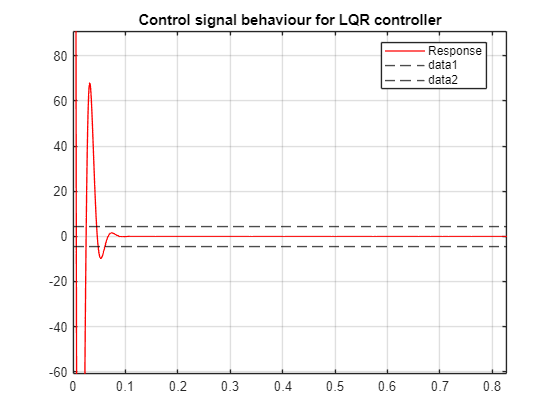

figure;

% Plot principale
plot(t, u_command, 'r', 'LineWidth', 1, 'DisplayName', 'Response');
hold on; % Mantiene il grafico attivo per aggiungere altre linee
yline(4.47,'k--');
yline(-4.47,'k--');
% Formattazione finale
title("Control signal behaviour for LQR controller");
legend('Location', 'best');
grid on; % Aggiunge la griglia per leggere meglio i valori
hold off;

xlim([0 1])
ylim([-10 10])

xlim([0.000 0.828])
ylim([-61 91])